% ******************************************************************
% * 04/06/2021
% * Arquivo parte 2
% * Simulação de transmissão de energia eléltrica entre duas antenas 
% * Marco Tulio Masselli Rainho Teixeira
% ******************************************************************

r1_int = 0.4;
r1_ext = 0.5;
n1 = 6;
antena_1 = spiralArchimedean('NumArms', 1, 'Turns', n1, 'InnerRadius', r1_int, 'OuterRadius', r1_ext, 'Tilt', 90,'TiltAxis', 'Y');
figure


% 2- Encontrando a frequência de ressonância 
f = linspace(15e6,19e6,150)

f = 	1.0e+07 *

    1.5000    1.5027    1.5054    1.5081    1.5107    1.5134    1.5161    1.5188    1.5215    1.5242    1.5268    1.5295    1.5322    1.5349    1.5376    1.5403    1.5430    1.5456    1.5483    1.5510    1.5537    1.5564    1.5591    1.5617    1.5644    1.5671    1.5698    1.5725    1.5752    1.5779    1.5805    1.5832    1.5859    1.5886    1.5913    1.5940    1.5966    1.5993    1.6020    1.6047    1.6074    1.6101    1.6128    1.6154    1.6181    1.6208    1.6235    1.6262    1.6289    1.6315


% f de ressonancia 6.439 MHz(de 1e6-10e6)
% f de ressonancia 17.68 MHz
f_ress = 17.68e6

f_ress = 17680000

fc = 1.615e7

fc = 16150000



z_1 = impedance(antena_1, f)

z_1 = 	1.0e+04 *

   0.0000 + 0.0451i   0.0000 + 0.0459i   0.0000 + 0.0466i   0.0000 + 0.0475i   0.0000 + 0.0483i   0.0000 + 0.0492i   0.0000 + 0.0501i   0.0000 + 0.0511i   0.0000 + 0.0522i   0.0000 + 0.0533i   0.0000 + 0.0544i   0.0000 + 0.0556i   0.0000 + 0.0570i   0.0000 + 0.0583i   0.0000 + 0.0598i   0.0000 + 0.0614i   0.0000 + 0.0631i   0.0000 + 0.0649i   0.0000 + 0.0669i   0.0000 + 0.0690i   0.0000 + 0.0713i   0.0000 + 0.0738i   0.0000 + 0.0765i   0.0000 + 0.0795i   0.0000 + 0.0828i   0.0000 + 0.0865i   0.0000 + 0.0906i   0.0000 + 0.0951i   0.0000 + 0.1003i   0.0000 + 0.1062i   0.0000 + 0.1130i   0.0000 + 0.1209i   0.0000 + 0.1301i   0.0000 + 0.1412i   0.0000 + 0.1547i   0.0001 + 0.1715i   0.0001 + 0.1930i   0.0001 + 0.2213i   0.0001 + 0.2607i   0.0002 + 0.3187i   0.0004 + 0.4134i   0.0008 + 0.5947i   0.0028 + 1.0837i   0.1248 + 7.0296i   0.0060 - 1.5118i   0.0012 - 0.6713i   0.0005 - 0.4267i   0.0003 - 0.3101i   0.0002 - 0.2419i   0.0001 - 0.1971i


plot(f, imag(z_1))
%hold on
grid on

imag(impedance(antena_1, 17.69e6))

ans = -0.0510



sigma = 24

sigma = 24



z_list = []


z_list =

     []



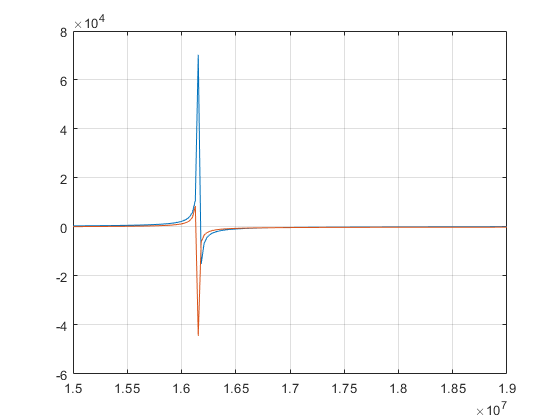

for n = 1: length(f)
    z_list(n) = sigma^2/(1i*f(n)*sigma/fc + fc*sigma/(1i*f(n))) + 4*f(n)*sigma/fc;
end


hold on 
plot(f, imag(z_list))
hold off

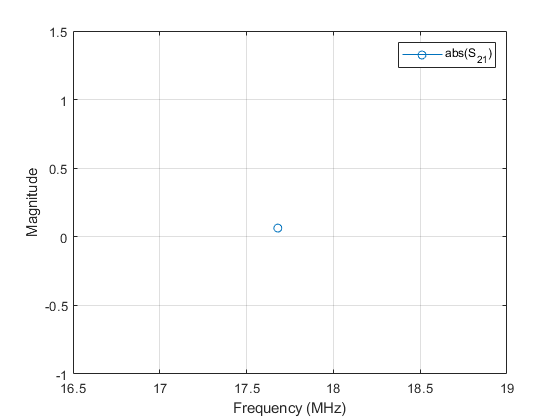



dist = linspace(0.05, 0.6, 10);
ganhos_f_ress = zeros(1,10);
for j = 1: length(dist)
    la_var = linearArray('Element', [antena_1, antena_1], 'ElementSpacing', dist(j));
    param_var = sparameters(la_var, f_ress);
    ganhos_freq_var = rfplot(param_var,2,1,'abs');
    ganhos_array = ganhos_freq_var.YData;
    ganhos_f_ress(1,j) = ganhos_array;
end



Rc = 1

Rc = 1

M = Rc*(ganhos_f_ress).^(1/2)/(f_ress*2*pi())

M = 	1.0e+-8 *

    0.8933    0.7789    0.5866    0.4635    0.3856    0.3332    0.2956    0.2673    0.2448    0.2263


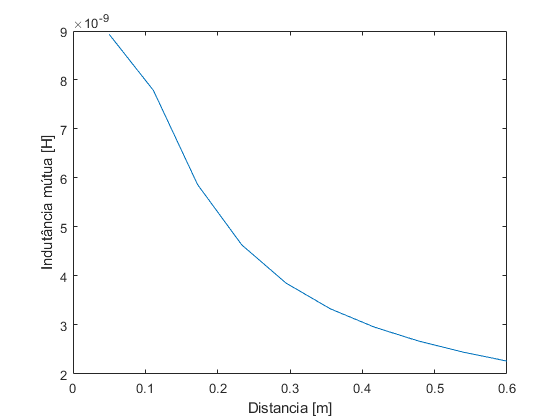

plot(dist, M)
ylabel('Indutância mútua [H]')
xlabel('Distancia [m]')